## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')  
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# INVERSE KINEMATIC 				

inverse kinematics problem consists of the determination of the joint variables corresponding to a given end-effector pose. 

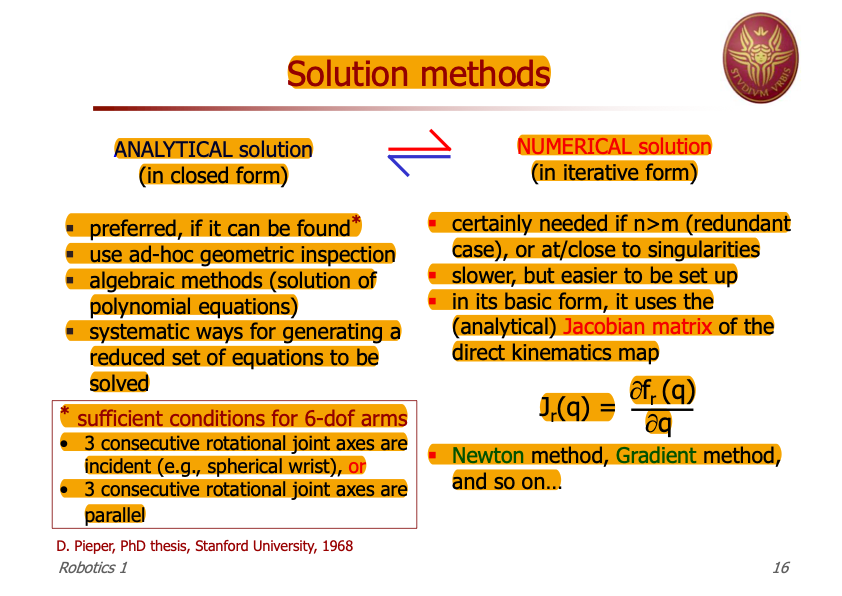

#  NUMERICAL APPROACH

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
syms alpha3 a3 d3 q3
syms alpha4 a4 d4 q4
syms alpha5 a5 d5 q5
syms alpha6 a6 d6 q6
syms alpha7 a7 d7 q7

# 2 LINK PLANAR ARM (2R)

disp('2 LINK PLANAR ARM (2R)')

2 LINK PLANAR ARM (2R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

type

type = 1×2 cell array
    {'r'}    {'r'}


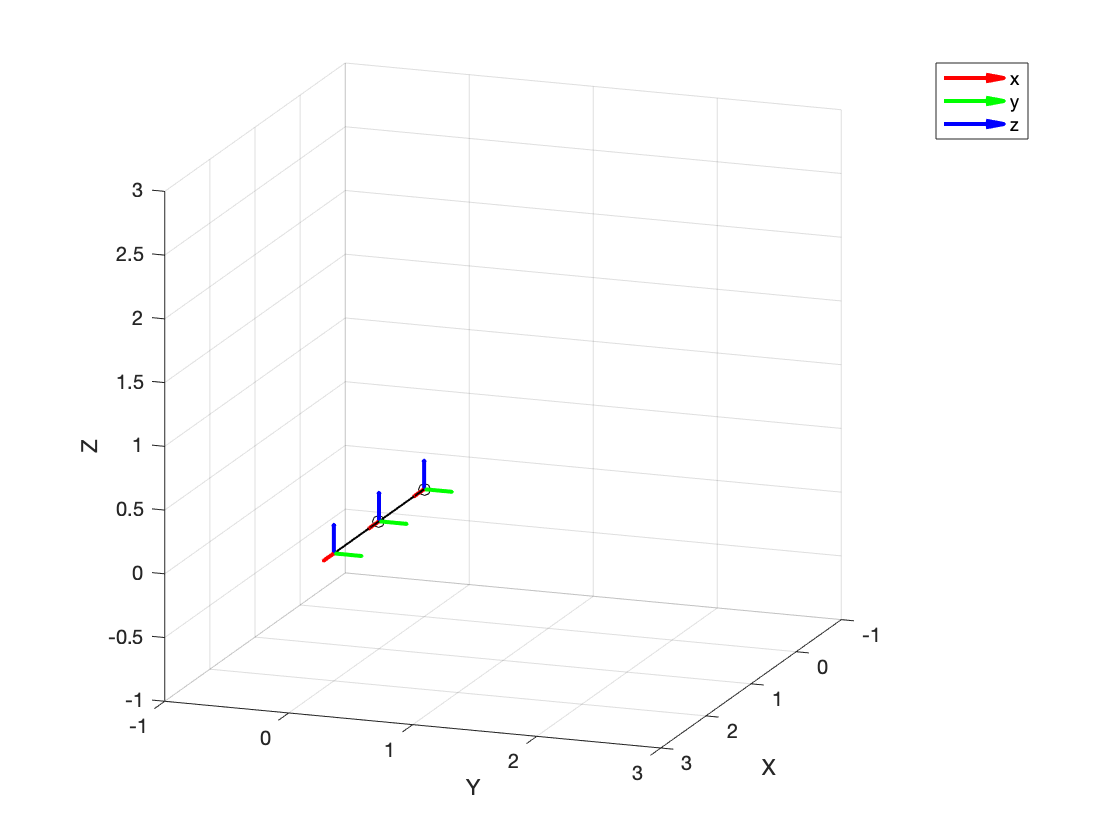


% DIRECT KINEMATIC
old = { a1, a2, q1, q2};

new = { 1, 1, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


% INVERSE KINEMATIC
rd = [1 1]'

rd =      1
     1



q_0 = [-pi pi/2]';

old = { a1, a2};

new = { 1, 1};

F_sym = subs(T_sym,old,new);

F_sym = F_sym(1:length(rd),4)

$$F\_sym = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}\right)$$


q_opt = SR_ROBO.newton(F_sym,q_0,rd); % NEWTON

iter : 5 
error : 0.000000 
q_opt : 
   -4.7124
    4.7124



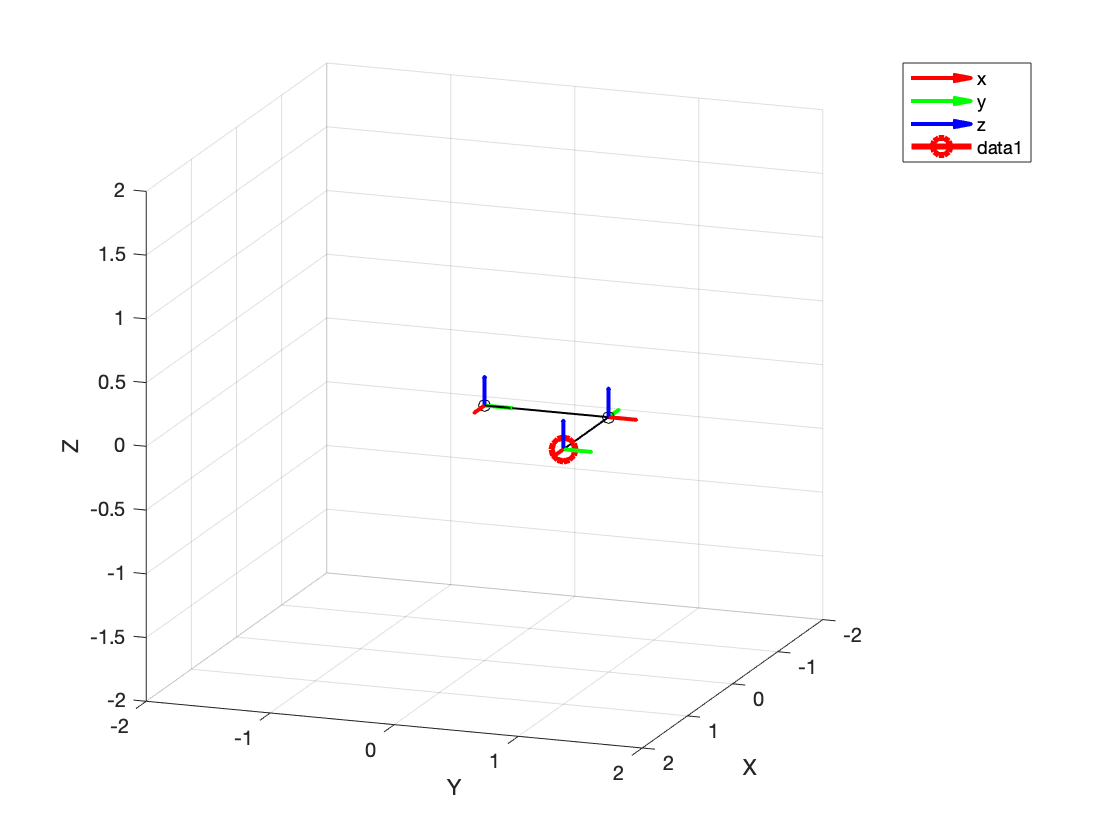


% APPLY SOLUTION
old = { a1, a2, q1, q2};

new = { 1, 1, q_opt(1), q_opt(2)};

A_list_opt = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list_opt{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list_opt,false);

hold on 

plot3(rd(1), rd(2), 0, '-ro', 'MarkerSize',12, "LineWidth",3)

hold off

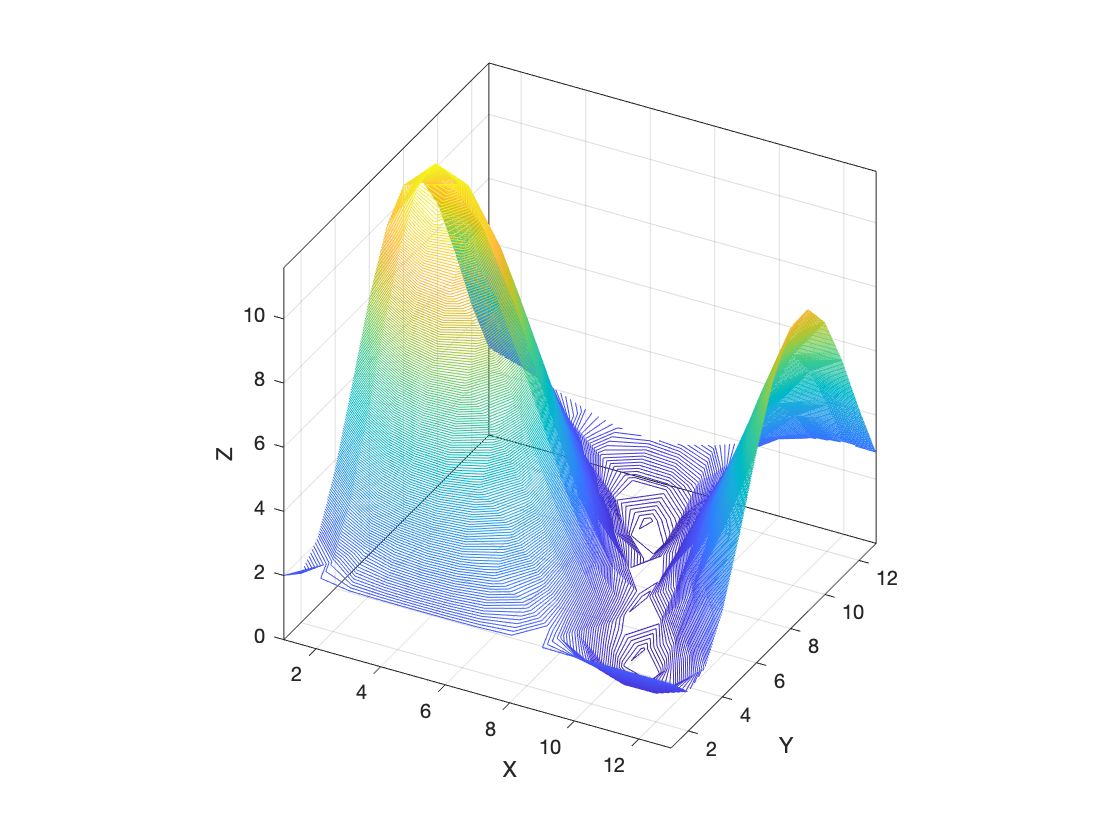


% PLOT SOLUTION SPACE
SR_ROBO.twojointspace(F_sym,rd);
xlim([1.0 13.0])
ylim([1.0 13.0])
zlim([0.0 11.6])
view([27.9 31.9])

# 3 LINK PLANAR ARM (3R)

disp('3 LINK PLANAR ARM (3R)')

3 LINK PLANAR ARM (3R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2;
    0   a3  0   q3];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 
       3        {'0'}     {'a3'}    {'0'}    {'q3'} 



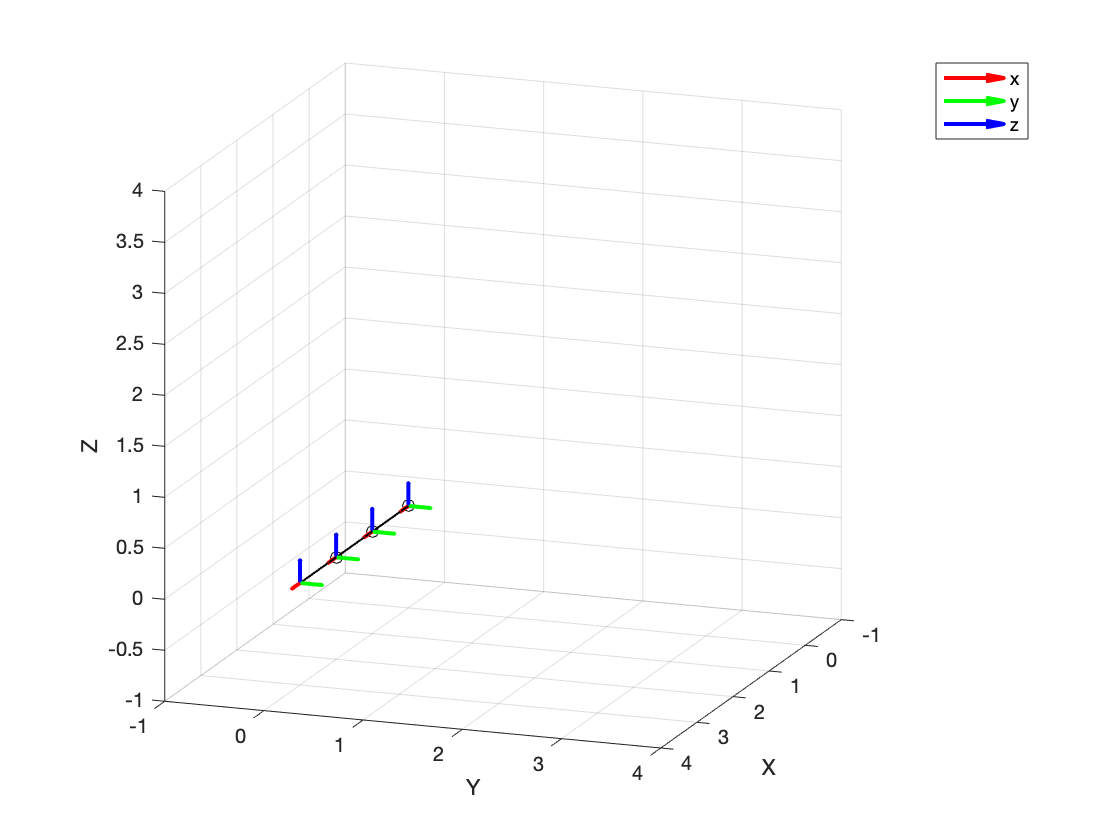


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, 0, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


% INVERSE KINEMATIC
% SINGULAR SOLUTIONS:
% - e NULL SPACE OF J'
% - J SINGULAR
% rd = [1 1]'
% q_0 = [pi/4 0 0]'; or
% q_0 = [-3*pi/4 0 0]';

rd = [1 1]'

rd =      1
     1



q_0 = [0 0 1]';

old = { a1, a2, a3};

new = { 1, 1, 1};

F_sym = subs(T_sym,old,new);

F_sym = F_sym(1:length(rd),4)

$$F\_sym = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{3}\right)\,\sigma_{1}-\sin\left(q_{3}\right)\,\sigma_{2}\\ \sin\left(q_{1}\right)+\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+\cos\left(q_{3}\right)\,\sigma_{2}+\sin\left(q_{3}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$


% M = 2 N = 3, non square jacobian
q_opt = SR_ROBO.grad(F_sym,q_0,rd, 0.7); % GRADIENT (if want to use newton need pseudoinverse

iter : 16 
error : 0.000052 
q_opt : 
    0.9327
    0.8642
    3.5951



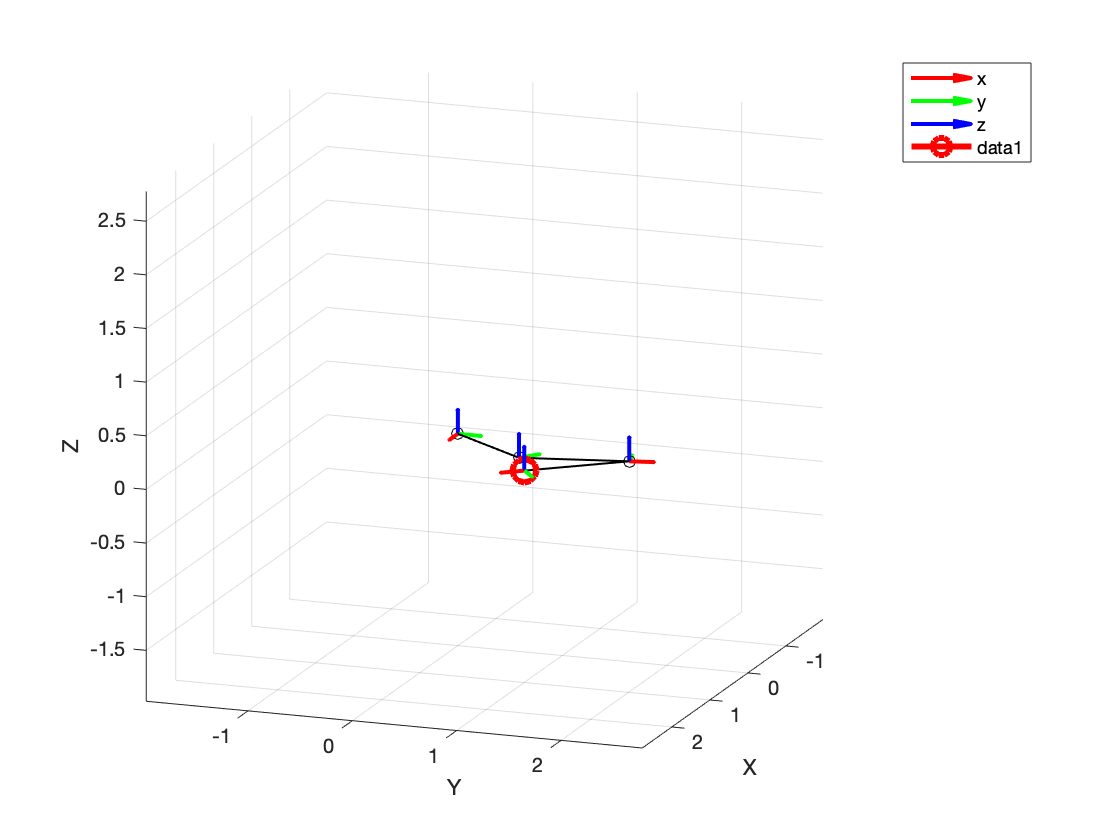


% APPLY SOLUTION
old = { a1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, q_opt(1), q_opt(2), q_opt(3)};

A_list_opt = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list_opt{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list_opt,false);

hold on 

plot3(rd(1), rd(2), 0, '-ro', 'MarkerSize',12, "LineWidth",3)

hold off

# ANTROPOMORPHIC ARM (3R)

disp('ANTROPOMORPHIC ARM (3R)')

ANTROPOMORPHIC ARM (3R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = ...
    [sym(pi/2)  0  d1   q1;
    0   a2  0   q2;
    0   a3  0   q3];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i      a_i       d_i      theta_i
    _______    ________    ______    ______    _______

       1       {'pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'   }    {'a2'}    {'0' }    {'q2'} 
       3       {'0'   }    {'a3'}    {'0' }    {'q3'} 



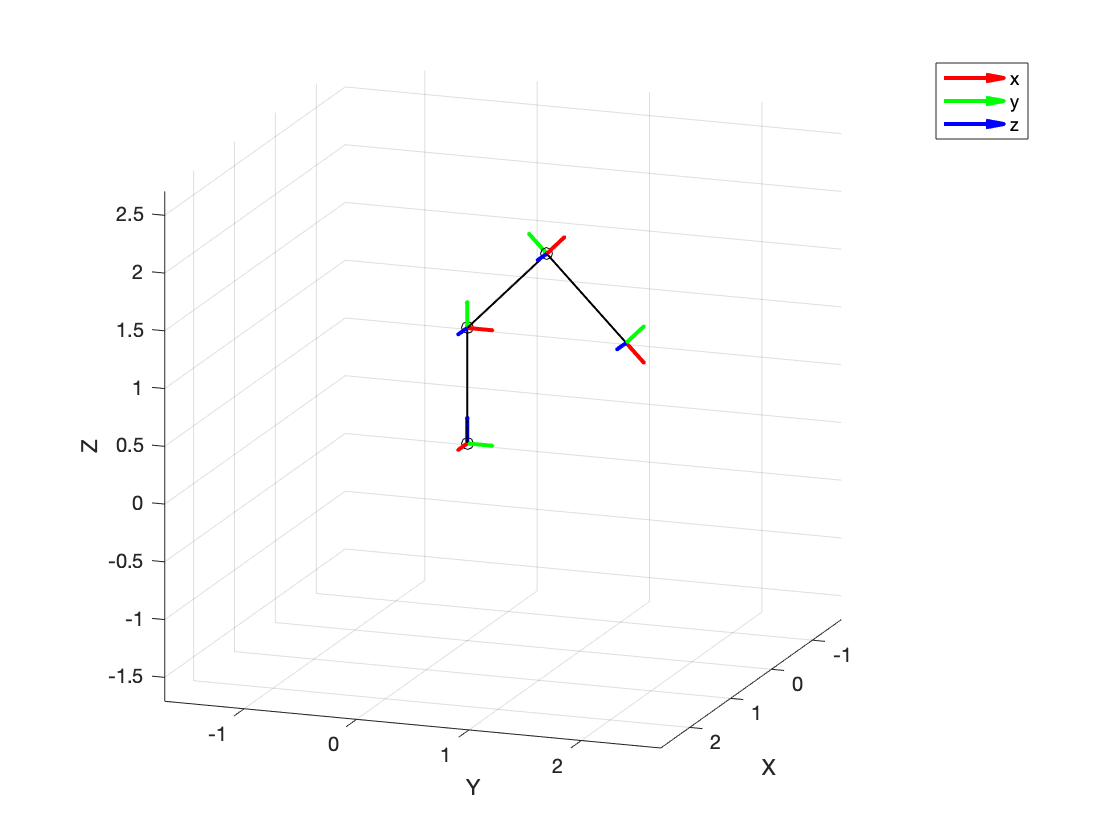


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, pi/2, pi/4, -pi/2};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


% INVERSE KINEMATIC
% SINGULAR SOLUTIONS:
% - e NULL SPACE OF J'
% - J SINGULAR
% rd = [1 1 1]'
% q_0 = [pi/4 0 0]'; or
% q_0 = [-3*pi/4 0 0]';

rd = [0.5 0.5 2]'

rd =     0.5000
    0.5000
    2.0000



q_0 = [ pi/2, pi/4, -pi/2]';

old = { d1, a2, a3};

new = { 1, 1, 1};

F_sym = subs(T_sym,old,new)

$$F\_sym = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{4}-\sigma_{2} & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\sigma_{4}-\sigma_{2}\\ \sigma_{3}-\sigma_{1} & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\sigma_{1}+\sigma_{3}\\ \sigma_{6}+\sigma_{5} & \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & 0 & \sin\left(q_{2}\right)+\sigma_{6}+\sigma_{5}+1\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{5}=\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}$$


F_sym = F_sym(1:length(rd),4)

$$F\_sym = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)+1 \end{array}\right)$$


J_q = jacobian(F_sym,symvar(F_sym))

$$J\_q = \begin{array}{l} \left(\begin{array}{ccc} \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{4}-\sigma_{3} & -\sigma_{4}-\sigma_{3}\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{2}-\sigma_{1} & -\sigma_{2}-\sigma_{1}\\ 0 & \cos\left(q_{2}\right)+\sigma_{6}-\sigma_{5} & \sigma_{6}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) \end{array}$$


q_opt = SR_ROBO.grad(F_sym,q_0,rd,0.8); % GRADIENT

iter : 20 
error : 0.000070 
q_opt : 
    0.7854
    1.8671
   -1.8234



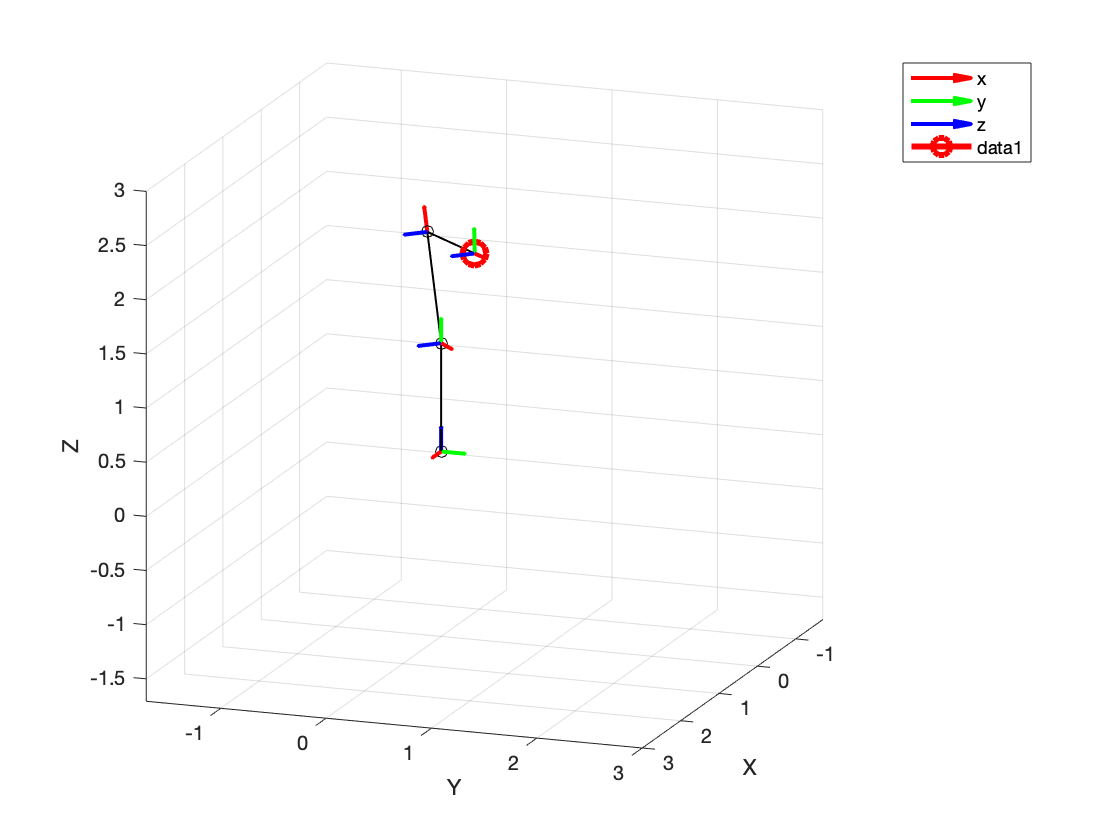


%q_opt = SR_ROBO.newton(F_sym,q_0,rd); % NEWTON


% APPLY SOLUTION
old = { d1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, q_opt(1), q_opt(2), q_opt(3)};

A_list_opt = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list_opt{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list_opt,false);

hold on 

plot3(rd(1), rd(2), rd(3), '-ro', 'MarkerSize',12, "LineWidth",3)

hold off

# POLAR ROBOT (2R P)

disp('POLAR ROBOT (2R P)')

POLAR ROBOT (2R P)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = ...
    [sym(-pi/2)   0  d1   q1;
    sym(pi/2)   0  0   q2;
    0   0  q3   0];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i      d_i      theta_i
    _______    _________    _____    ______    _______

       1       {'-pi/2'}    {'0'}    {'d1'}    {'q1'} 
       2       {'pi/2' }    {'0'}    {'0' }    {'q2'} 
       3       {'0'    }    {'0'}    {'q3'}    {'0' } 



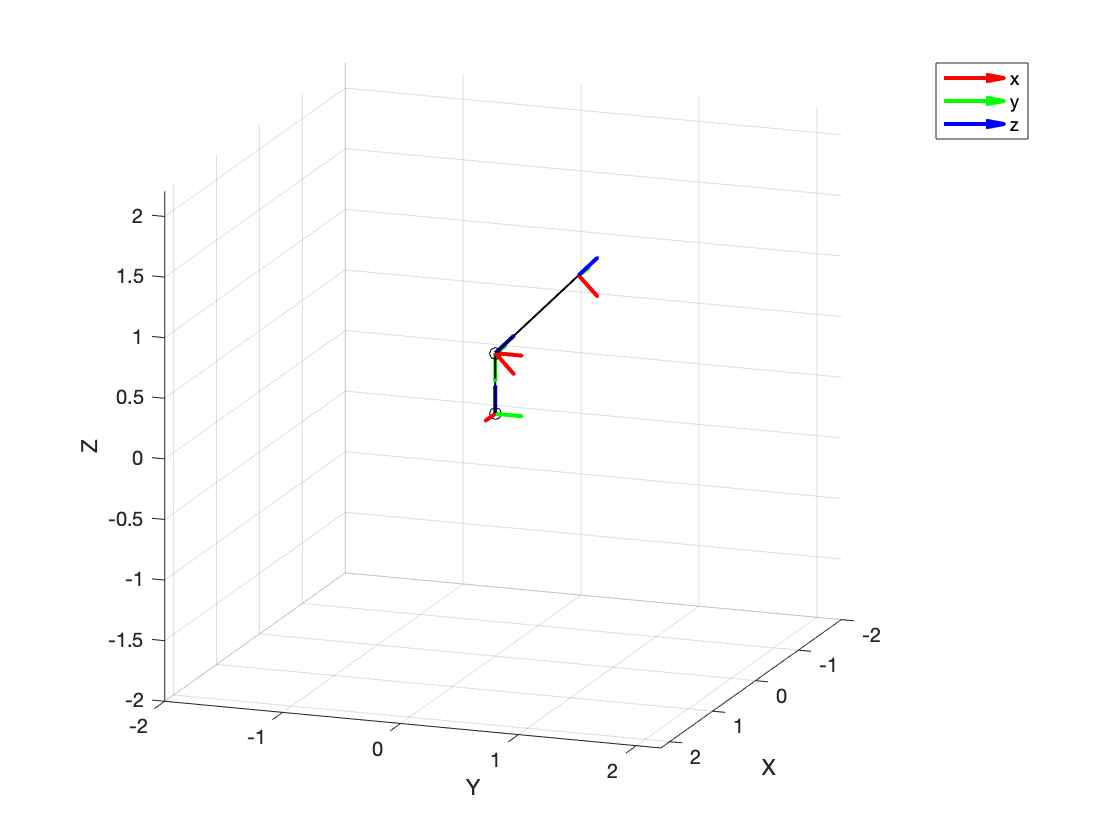


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, q1, q2, q3};

new = { 0.5, pi/2, pi/4, 1};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);


% INVERSE KINEMATIC
% SINGULAR SOLUTIONS:
% - e NULL SPACE OF J'
% - J SINGULAR
% rd = [1 1]'
% q_0 = [pi/4 0 0]'; or
% q_0 = [-3*pi/4 0 0]';

rd = [1 1 1]'

rd =      1
     1
     1



q_0 = [pi/2 pi/2 1]';

old = { d1};

new = { 0.5};

F_sym = subs(T_sym,old,new)

$$F\_sym = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)+\frac{1}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


F_sym = F_sym(1:length(rd),4)

$$F\_sym = \left(\begin{array}{c} q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{2}\right)+\frac{1}{2} \end{array}\right)$$


J_q = jacobian(F_sym,symvar(F_sym))

$$J\_q = \left(\begin{array}{ccc} -q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ q_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & q_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & -q_{3}\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right) \end{array}\right)$$


%q_opt = SR_ROBO.grad(F_sym,q_0,rd,0.1); % GRADIENT

q_opt = SR_ROBO.newton(F_sym,q_0,rd); % NEWTON

iter : 4 
error : 0.000065 
q_opt : 
    0.7854
    1.2310
    1.5000



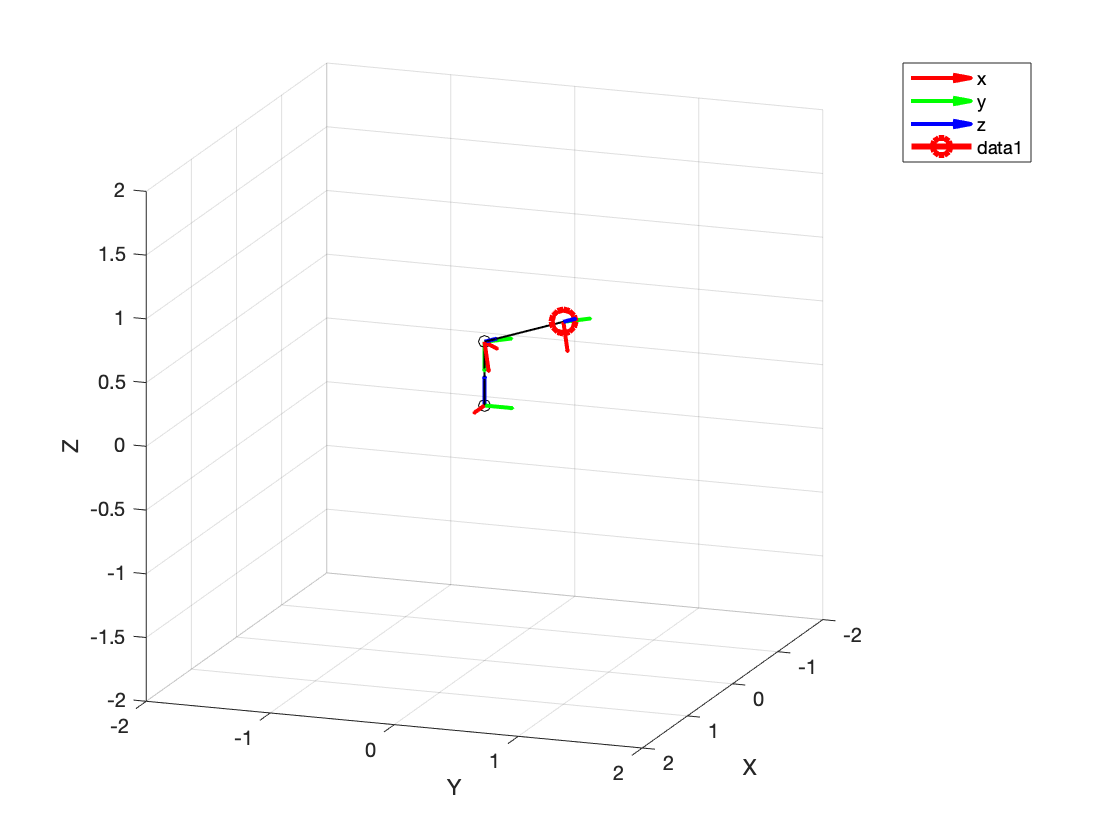



% APPLY SOLUTION
old = { d1, q1, q2, q3};

new = { 0.5, q_opt(1), q_opt(2), q_opt(3)};

A_list_opt = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list_opt{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list_opt,false);

hold on 

plot3(rd(1), rd(2), rd(3), '-ro', 'MarkerSize',12, "LineWidth",3)

hold off

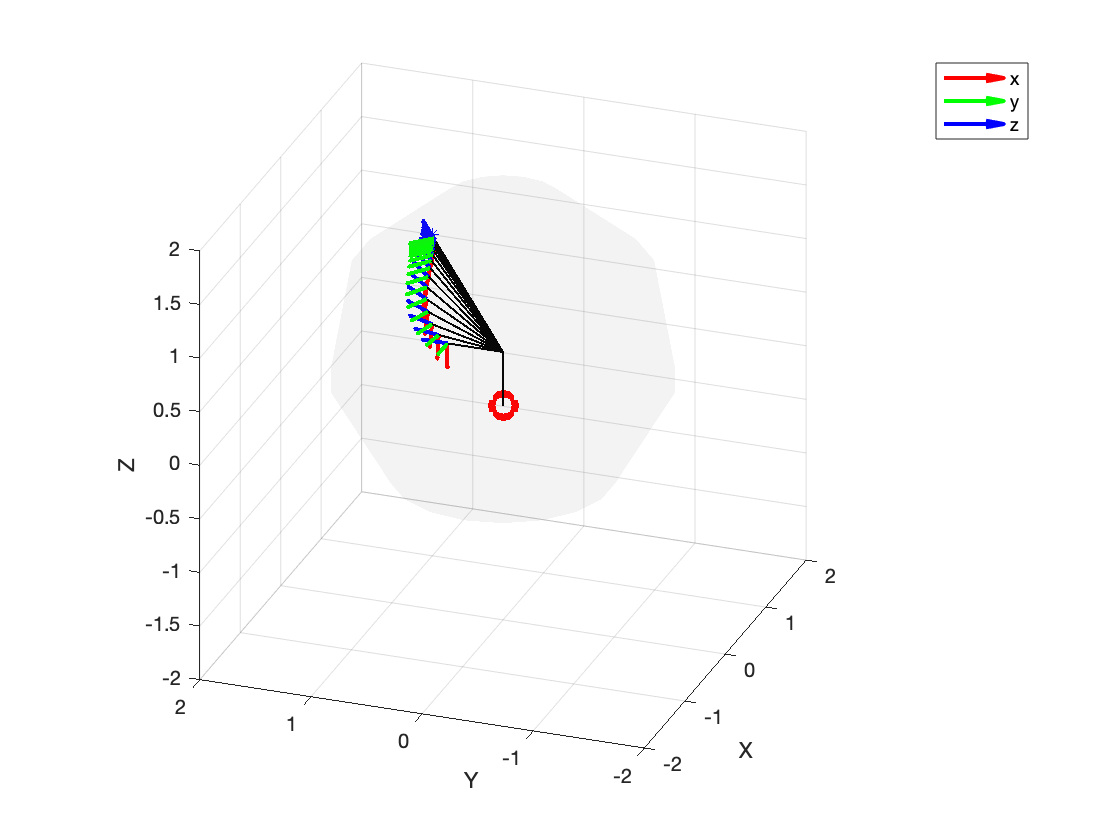


% SIMULINK MODEL
timeStep=0.01;
startTime=0;
endTime=5;
numSteps=endTime/timeStep;
timeVector = timeStep * [startTime:numSteps-1]';

q_0_polar_2RP = [pi/2 pi/2 0.5]';
r_d = [1 1 1]';

r_d_polar_2RP.time = timeVector;
r_d_polar_2RP.signals.values = [zeros(size(timeVector)) zeros(size(timeVector)) zeros(size(timeVector))];
r_d_polar_2RP.signals.dimensions = 3;
for k=1:length(timeVector)
    r_d_polar_2RP.signals.values(k,:)= r_d';
end

simOut = sim('POLAR_2RP_IK',endTime);


clf;

t1=linspace(-180,180,10)*pi/180;
t2=linspace(-180,180,10)*pi/180;
t3=linspace(0,1.5,10);
[t1,t2,t3]=ndgrid(t1,t2,t3);
old = { d1, q1, q2, q3};
new = { 0.5, t1, t2, t3};
radius = 2;
% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

pbaspect([1 1 1])

hold on

plot3(r_d(1),r_d(2),r_d(3),'b*')

% PLOT RESULT
for i=1:length(timeVector)
    
    if mod(i-1,30)==0
        q = simOut.q_polar_2RP.Data(i,:);
        
        new_ = { 0.5, q(1), q(2), q(3)};
        
        SR_ROBO.draw_clean(A_list_sym,old,new_,radius,false);
        
        view([-70 25]);

        drawnow
    end
    
end

hold off